# Calcolo Numerico con Laboratorio

# Compito a casa 

# 27 settembre 2021

## Esercizio 1 

Si consideri la funzione 

$f(x)=\frac1{(e^{x+0.2}-1)^2+0.05}+\frac{10}{\cos(x)+1.2}$   per $x\in[-3,7]$.

- Per ogni valore di `n=1:3:10 `calcolare il polinomio interpolatore di grado `n` utilizzando `n+1` nodi equispaziati nell'intervallo dato.

- Calcolare l'errore massimo per ciascun valore di `n`.

- Riportare in 4 figure la funzione con i polinomi interpolatori di grado diverso. Completare le figure con la legenda e il titolo. 

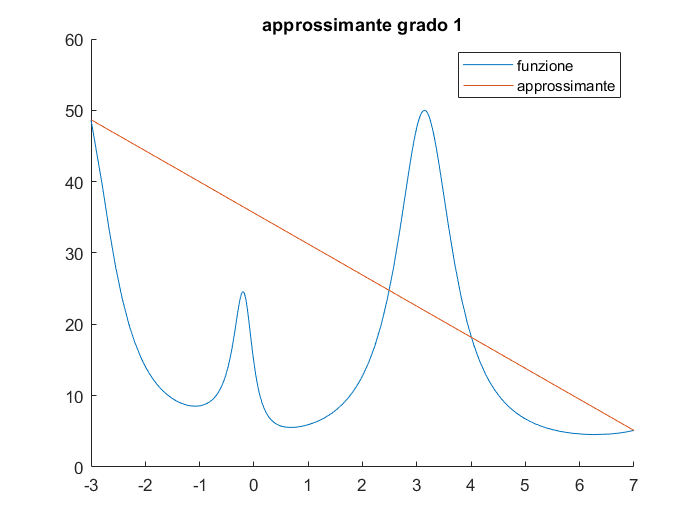

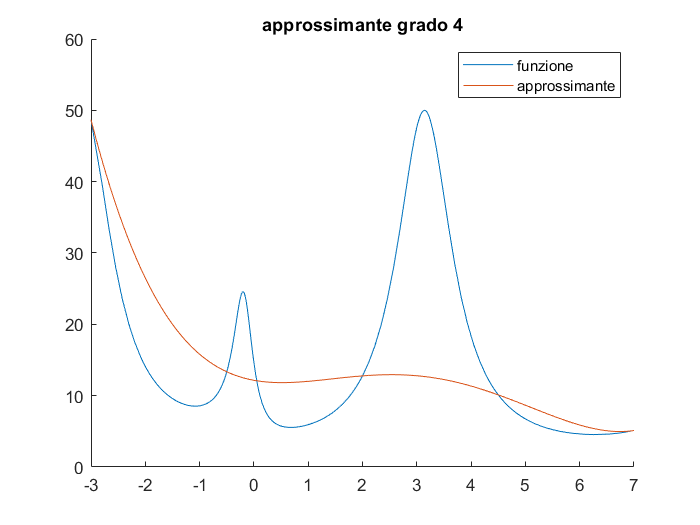

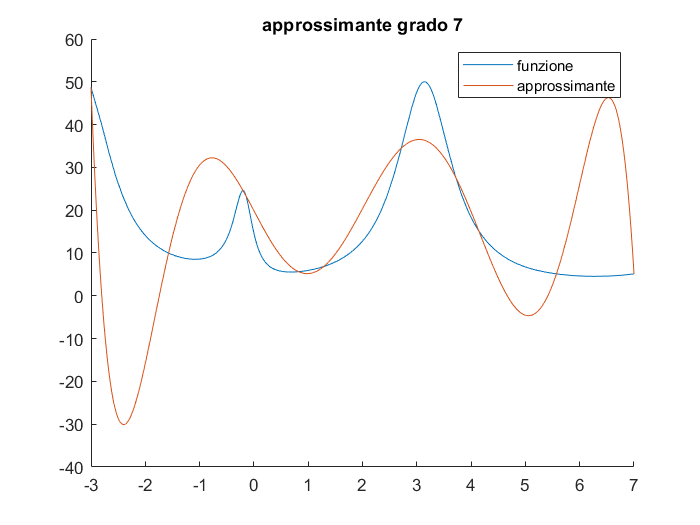

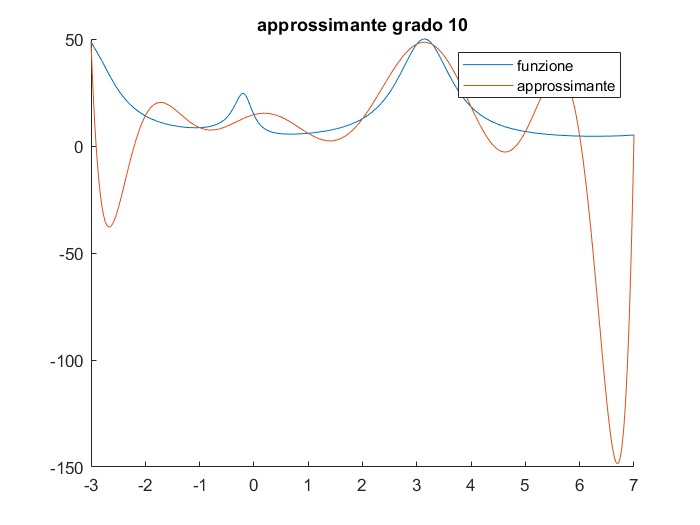

clear all
f=@(x) 1./((exp(x+0.2)-1).^2+0.05)+10./(cos(x)+1.2);
N=1:3:10;
int=[-3 7];
for n=N
    p=calcPoly(int,n,f);
    figure()
    hold on
    fplot(f,int)
    plotPoly(p,int)
    title("approssimante grado "+n)
    legend("funzione","approssimante")
end

nerr=2.5:3:8.5;
err=norm(f(nerr)-polyval(p,nerr),inf)

err = 3.8160e+04

## Esercizio 2

Si consideri la funzione $f(x)=e^x$, per $x\in[-1,1]$.

- Interpolare con polinomi di grado **pari** $n=2,\dots,12$, la funzione data, usando $n+1$ punti equispaziati nell'intervallo $[-1,1]$.

- Riportare il grafico di ciascun polinomio interpolatore insieme con quello della funzione data.

- Calcolare l'errore commesso ossia    $E_n=\max_{a\le x\le b}|f(x)-\Pi_n(x)|$.

- Costruire un vettore contenente gli errori ottenuti per tutti i valori di $n$ e riportare gli errori in un grafico in scala semilogaritmica `semilogy(n,E) `essendo `n` ed `E`  i vettori contenenti rispettivamente i valori dei gradi dei polinomi usati e i corrispondenti valori dell'errore.

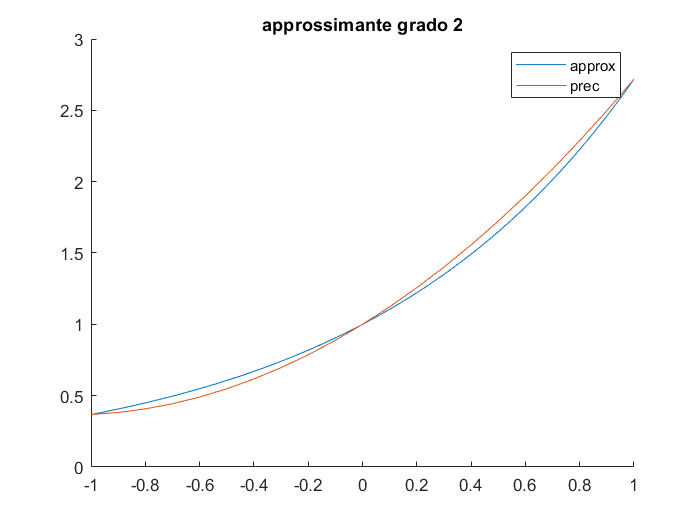

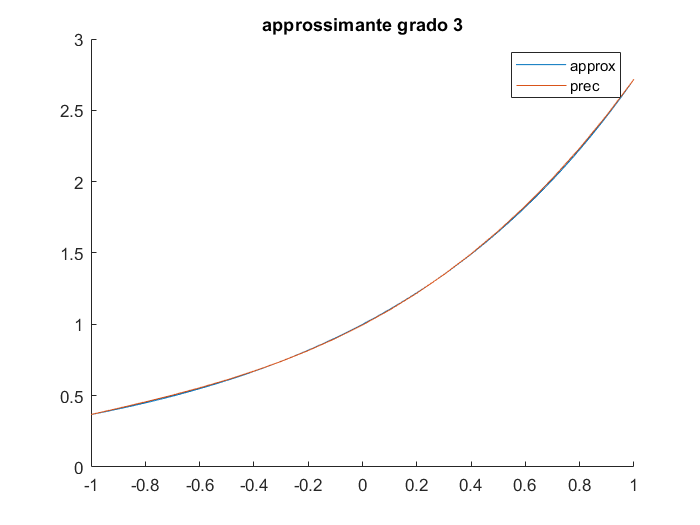

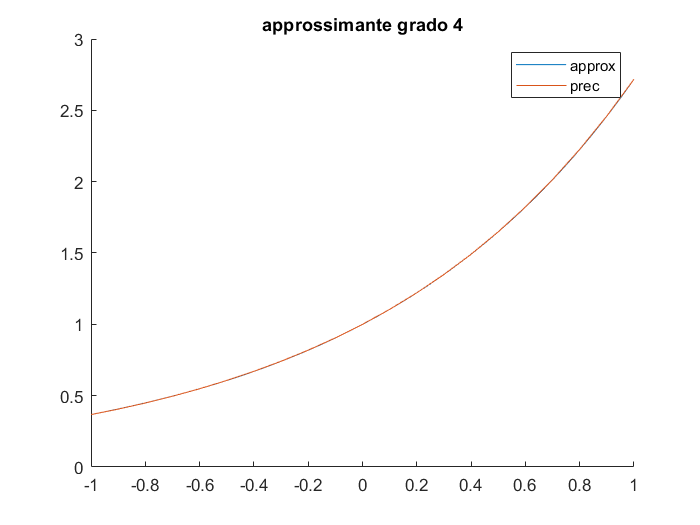

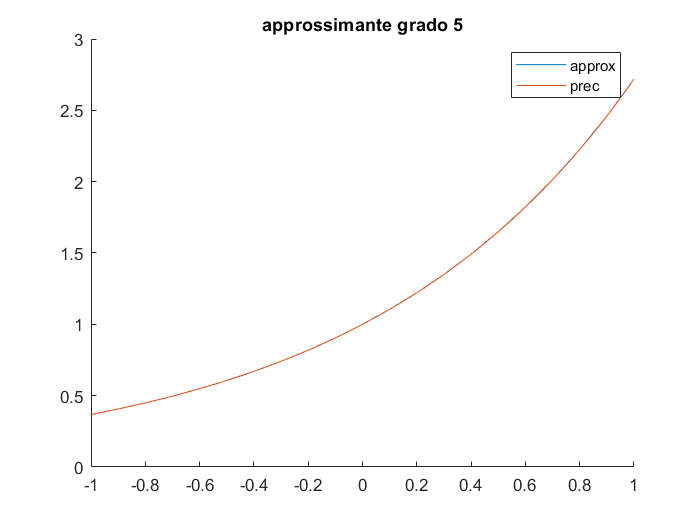

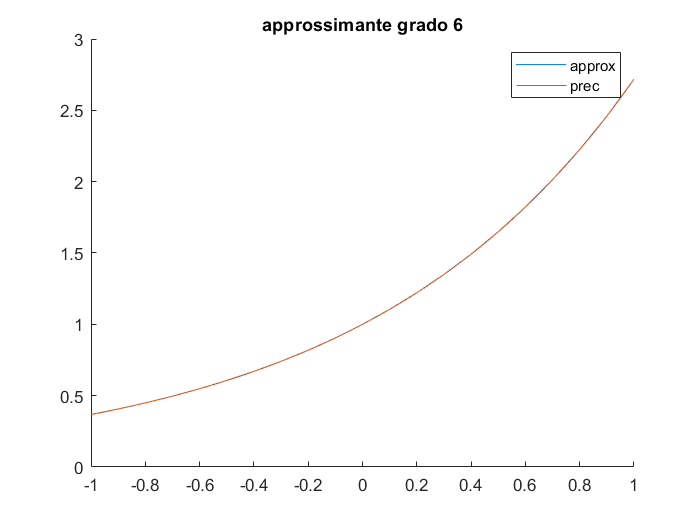

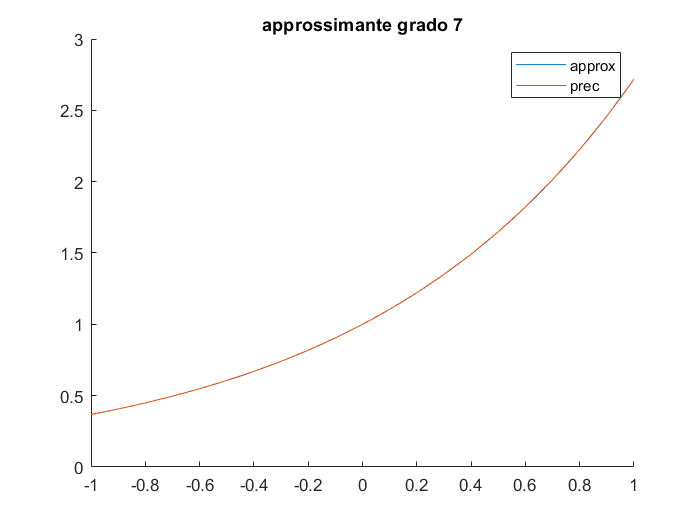

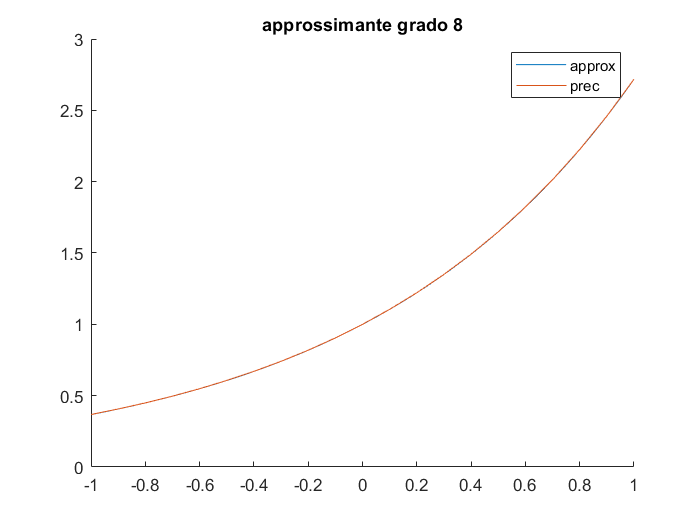

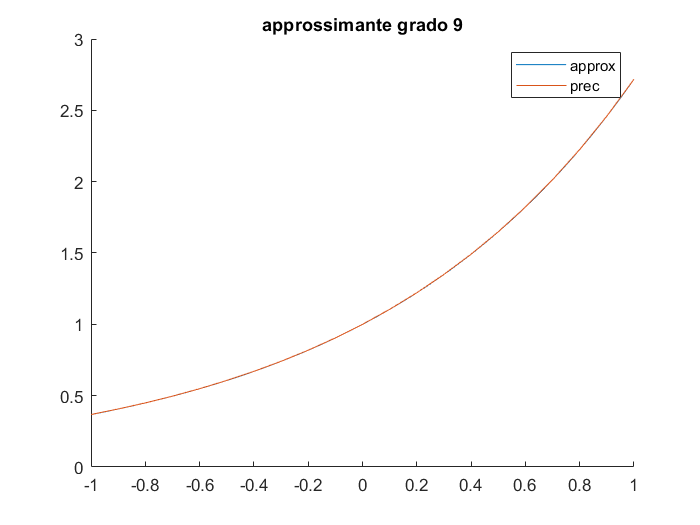

clear all
f=@(x) exp(x);
N=100;
n=linspace(-1,1,N);
fn=f(n);
for i=2:1:20
    figure()
    hold on
    fplot(f,[-1 1])
    x=linspace(-1,1,i+1);
    y=f(x);
    p=polyfit(x,y,i);
    x1=-1:0.1:1;
    y=polyval(p,x1);
    plot(x1,y)
    err1(i-1)=norm(fn-polyval(p,n),inf);
    title("approssimante grado "+i)
    legend("approx","prec")
end

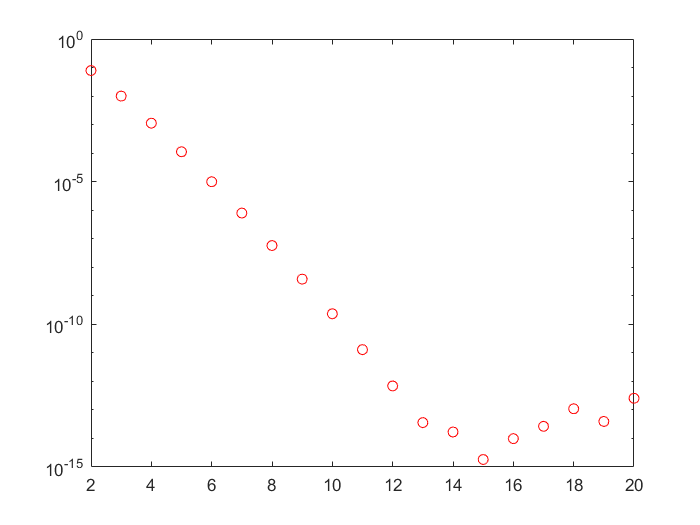

figure()
semilogy(2:20,err1,"or")